# Lab 11 Sessió 1

BW = rgb2gray(imread("Abecedari.png"));
imshow(BW);

BW = BW < 200;
BWU = BW; BWU(end/2:end, :) = 0;

BWD = BW; BWD(1:end/2, :) = 0;

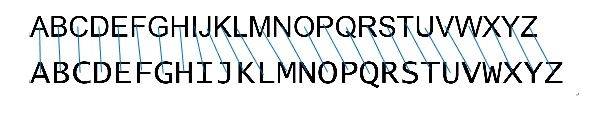


CCU = bwconncomp(BWU);
CCD = bwconncomp(BWD);

propsU = regionprops('table', CCU, 'Centroid');
propsD = regionprops('table', CCD, 'Centroid');

FU = extractHOGFeatures(BWU, propsU.Centroid, "CellSize", [16 16], "BlockSize", [3 3]);
FD = extractHOGFeatures(BWD, propsD.Centroid, "CellSize", [16 16], "BlockSize", [3 3]);

NumObj = CCU.NumObjects;

A = zeros(NumObj, NumObj);
for i = 1 : NumObj
    for j = 1 : NumObj
        A(j, i) = norm(FU(i, :) - FD(j, :));
    end
end

costUnmatched = max(A, [], 'all');
Assig = matchpairs(A, costUnmatched);

hold on
for i = 1 : NumObj
    line( [propsU.Centroid(i, 1), propsD.Centroid(Assig(i), 1)], [propsU.Centroid(i, 2), propsD.Centroid(Assig(i), 2)] );
end
hold off

## Exercici: Harris

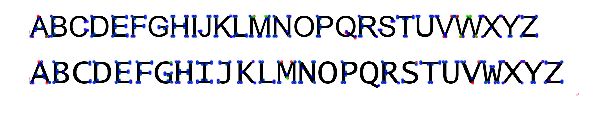

BW = rgb2gray(imread("Abecedari.png"));
imshow(BW);

wsize = 5;
kp = calculateKeyPoints(BW, wsize);
imshow(BW);

hold on
for i = 1 : size(kp, 1)
    rectangle('Position', [kp.Centroid(i, 1) - wsize/2, kp.Centroid(i, 2) - wsize/2, wsize, wsize], 'EdgeColor','r')
end

% Més window
kp = calculateKeyPoints(BW, 15);
for i = 1 : size(kp, 1)
    rectangle('Position', [kp.Centroid(i, 1) - wsize/2, kp.Centroid(i, 2) - wsize/2, wsize, wsize], 'EdgeColor','g')
end

% Menys window
kp = calculateKeyPoints(BW, 2);
for i = 1 : size(kp, 1)
    rectangle('Position', [kp.Centroid(i, 1) - wsize/2, kp.Centroid(i, 2) - wsize/2, wsize, wsize], 'EdgeColor','b')
end

Conclusió canvi mida: El qué és un vertex depén de la mida de la finestra.

function kp = calculateKeyPoints(I, wsize)
    I = double(I);
    h = [1, 2, 1; 0, 0, 0; -1, -2, -1] /4;

    dx = imfilter(I, h, 'replicate');
    dy = imfilter(I, h', 'replicate');
    
    dxy = dx .* dy;
    
    dx2 = dx .^ 2;
    dy2 = dy .^ 2;

    dxy2 = dxy .^ 2;
    
    h = fspecial('gaussian', wsize, wsize/4);
    sum_dx2 = imfilter(dx2, h, 'replicate');
    sum_dy2 = imfilter(dy2, h, 'replicate');
    sum_dxy2 = imfilter(dxy2, h, 'replicate');
   
    k = 0.05;
    R = sum_dx2 .* sum_dy2 - sum_dxy2 - k* (sum_dx2 + sum_dy2) .^ 2;
    
    dR = imdilate(R, ones([3, 3]));
    M = mean(R, 'all') + 0.7 * std(R, [], 'all');

    lM = dR == R & R > M;

    kp = regionprops('table', lM, 'Centroid');

end